A=[0 -2
    1 -7]

A =      0    -2
     1    -7


B=[1
    5]

B =      1
     5


C=[1 6]

C =      1     6


I = eye(2)

I =      1     0
     0     1


syms p
W = C * inv(p*I-A)*B

$$W = \frac{30\,p}{p^{2}+7\,p+2}-\frac{4}{p^{2}+7\,p+2}+\frac{p+7}{p^{2}+7\,p+2}$$


$$\begin{array}{l}
\mathrm{Определяем}\;\mathrm{передаточную}\;\mathrm{функцию}\;\mathrm{системы}\\
W\left(p\right)=C{\left(pI-A\right)}^{-1} \cdot B=\left\lbrack \begin{array}{cc}
1 & 6
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{cc}
p & 2\\
-1 & p+7
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{c}
1\\
6
\end{array}\right\rbrack =\frac{31p+3}{p^2 +7\,p+2}
\end{array}$$


simtime = 20

simtime = 20

first = sim("Task5.slx", simtime)

first =   Simulink.SimulationOutput:

                  simin: [1x1 timeseries] 
                 simout: [1x1 timeseries] 
                   tout: [60x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


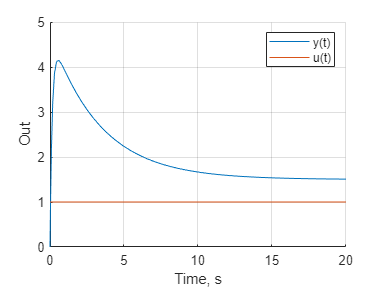

hold on
plot(first.simout.Time, first.simout.Data)
plot(first.simin.Time, first.simin.Data)

xlabel("Time, s")
ylabel("Out")
grid on
legend(["y(t)","u(t)"])